[T1,Y1] = analytic([0;0.6],0.01,2)

T1 =          0
    0.0100
    0.0200
    0.0300
    0.0400
    0.0500
    0.0600
    0.0700
    0.0800
    0.0900


Y1 =          0    0.6000
    0.0054    0.0054
    0.0098    0.0098
    0.0134    0.0134
    0.0162    0.0162
    0.0185    0.0185
    0.0202    0.0202
    0.0215    0.0215
    0.0224    0.0224
    0.0230    0.0230


plot(T1,Y1(:,1),"r")
hold on

[T,Y] = eulersolver([0;0.6],0.01,2,@derivs)

T =          0
    0.0100
    0.0200
    0.0300
    0.0400
    0.0500
    0.0600
    0.0700
    0.0800
    0.0900


Y =          0    0.6000
    0.0060    0.4800
    0.0108    0.3802
    0.0146    0.2972
    0.0176    0.2284
    0.0199    0.1715
    0.0216    0.1245
    0.0228    0.0858
    0.0237    0.0540
    0.0242    0.0281


plot(T,Y(:,1),"g")
hold on

[T,Y] = eulersolver([0;0.6],0.05,2,@derivs)

T =          0
    0.0500
    0.1000
    0.1500
    0.2000
    0.2500
    0.3000
    0.3500
    0.4000
    0.4500


Y =          0    0.6000
    0.0300   -0.0000
    0.0300   -0.0960
    0.0252   -0.0960
    0.0204   -0.0806
    0.0164   -0.0653
    0.0131   -0.0524
    0.0105   -0.0419
    0.0084   -0.0336
    0.0067   -0.0268


plot(T,Y(:,1),"g--")
hold on

[T,Y] = eulersolver([0;0.6],0.1,2,@derivs)

T =          0
    0.1000
    0.2000
    0.3000
    0.4000
    0.5000
    0.6000
    0.7000
    0.8000
    0.9000


Y =          0    0.6000
    0.0600   -0.6000
   -0.0000    0.2160
    0.0216   -0.2160
   -0.0000    0.0778
    0.0078   -0.0778
   -0.0000    0.0280
    0.0028   -0.0280
   -0.0000    0.0101
    0.0010   -0.0101


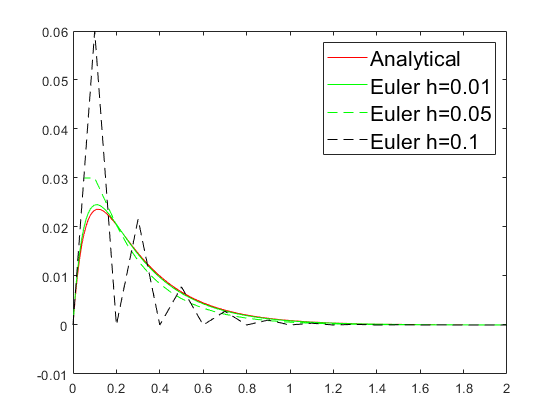

plot(T,Y(:,1),"k--")


xlim([0,2])
legend({"Analytical","Euler h=0.01","Euler h=0.05","Euler h=0.1"},'FontSize',16)